clc
clear all
close all

x = linspace(-2,2,100);

LAD = abs(x)

LAD =     2.0000    1.9596    1.9192    1.8788    1.8384    1.7980    1.7576    1.7172    1.6768    1.6364    1.5960    1.5556    1.5152    1.4747    1.4343    1.3939    1.3535    1.3131    1.2727    1.2323    1.1919    1.1515    1.1111    1.0707    1.0303    0.9899    0.9495    0.9091    0.8687    0.8283    0.7879    0.7475    0.7071    0.6667    0.6263    0.5859    0.5455    0.5051    0.4646    0.4242    0.3838    0.3434    0.3030    0.2626    0.2222    0.1818    0.1414    0.1010    0.0606    0.0202



LS  = power(x,2)

LS =     4.0000    3.8400    3.6833    3.5298    3.3797    3.2327    3.0891    2.9487    2.8115    2.6777    2.5471    2.4198    2.2957    2.1749    2.0573    1.9431    1.8321    1.7243    1.6198    1.5186    1.4207    1.3260    1.2346    1.1464    1.0615    0.9799    0.9015    0.8264    0.7546    0.6861    0.6208    0.5587    0.4999    0.4444    0.3922    0.3432    0.2975    0.2551    0.2159    0.1800    0.1473    0.1179    0.0918    0.0690    0.0494    0.0331    0.0200    0.0102    0.0037    0.0004



delta = 1

delta = 1

set_1 = abs(x) <= delta;
set_2 = abs(x) > delta;

Huber = 0.5*set_1.*power(x,2) + set_2.*(abs(x) - 0.5)

Huber =     1.5000    1.4596    1.4192    1.3788    1.3384    1.2980    1.2576    1.2172    1.1768    1.1364    1.0960    1.0556    1.0152    0.9747    0.9343    0.8939    0.8535    0.8131    0.7727    0.7323    0.6919    0.6515    0.6111    0.5707    0.5303    0.4900    0.4508    0.4132    0.3773    0.3430    0.3104    0.2794    0.2500    0.2222    0.1961    0.1716    0.1488    0.1275    0.1079    0.0900    0.0737    0.0590    0.0459    0.0345    0.0247    0.0165    0.0100    0.0051    0.0018    0.0002


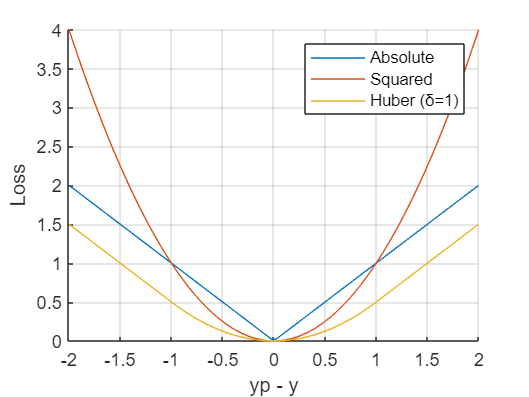


hold on
grid on
xlim([-2,2]);
xticks(-2:0.5:2);
ylim([0,4]);
yticks(0:0.5:4);

% Error = actual - predicted
xlabel("yp - y")
ylabel("Loss")
plot(x, LAD)
plot(x, LS)
plot(x, Huber)
legend('Absolute', 'Squared', 'Huber (δ=1)')